# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.2 带有误差线的柱状图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

也有一个开源函数 barweb 可用，链接如下：

[https://ww2.mathworks.cn/matlabcentral/fileexchange/10803-barweb-bargraph-with-error-bars](https://ww2.mathworks.cn/matlabcentral/fileexchange/10803-barweb-bargraph-with-error-bars)

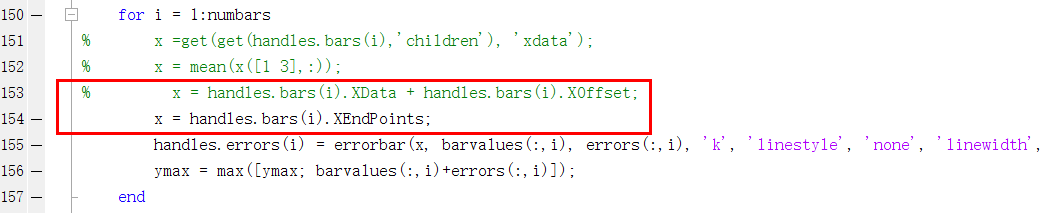

Matlab2020b 测试报错，将 151 和 152 行代码注释掉，换成 153 行 或者 154 行都可以正常运行，个人觉得灵活性较差；

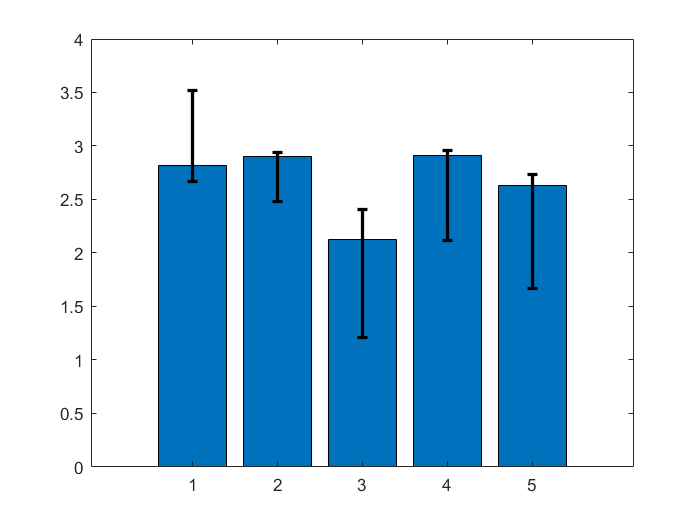

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 生成示例数据
m = 5;
n = 3;
x = 1:m;
y = rand(m, n) + 2;
% 误差限
neg = rand(m, n);
pos = rand(m, n);
% 单系列带有误差线的柱状图
figure;
bar(x, y(:, 1));
hold on
errorbar(x, y(:, 1), neg(:, 1), pos(:, 1), 'LineStyle', 'none', 'Color', 'k', 'LineWidth', 2);
hold off

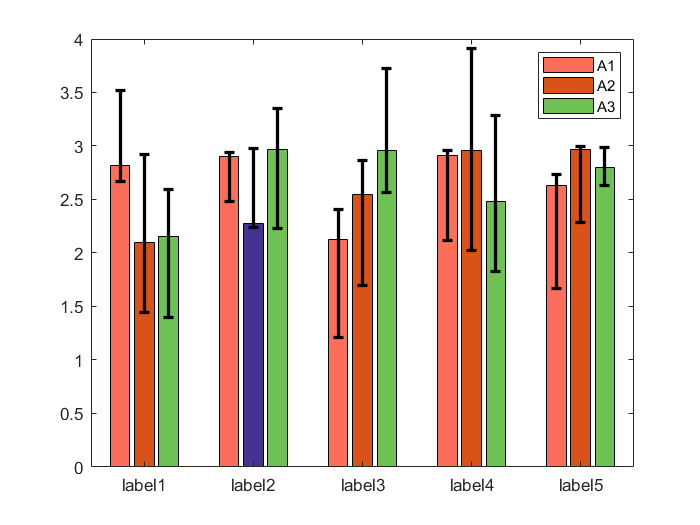

% 多系列带有误差线的柱状图
figure;
% 绘制柱状图
h = bar(x, y);
% 设置每个系列颜色
for i = 1:length(h)
    h(1, i).FaceColor = all_colors(i, :);
end
% 单独设置第二个系列第二个柱子颜色
% 这行代码少不了
h(1, 2).FaceColor = 'flat';
h(1, 2).CData(2,:) = all_colors(6, :); 
% 获取误差线 x 值 
% 也就是 XEndPoints 的值
xx = zeros(m, n);
for i = 1 : n
    xx(:, i) = h(1, i).XEndPoints'; 
end
% 绘制误差线
hold on
errorbar(xx, y, neg, pos, 'LineStyle', 'none', 'Color', 'k', 'LineWidth', 2);
hold off
% 绘制图例
legend({'A1', 'A2', 'A3'});
% 设置 x 轴标签
set(gca, 'XTickLabel', {'label1', 'label2', 'label3', 'label4', 'label5'});

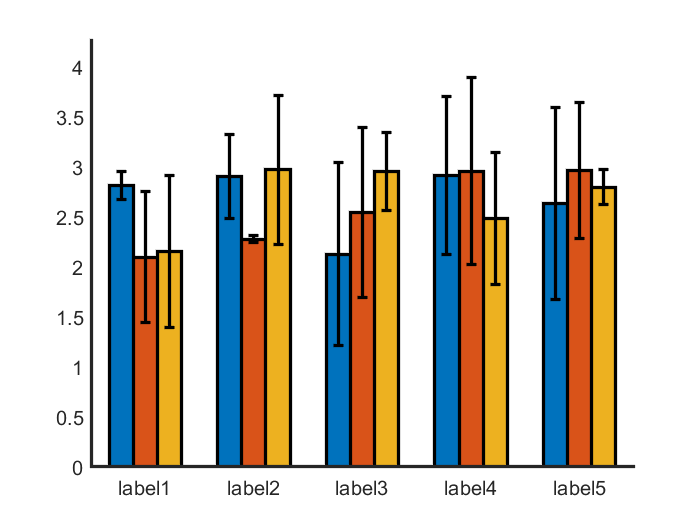

% 试试 barweb
figure;
barweb(y, neg, 1, {'label1', 'label2', 'label3', 'label4', 'label5'});